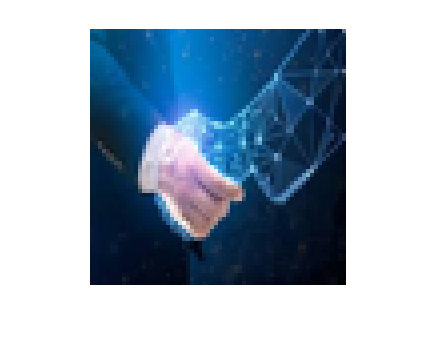

clear all;
close all;

hand = imread("hand.jpg");
hand64 = imresize(hand,[64 64]);
figure
imshow(hand64, 'InitialMagnification', 400)

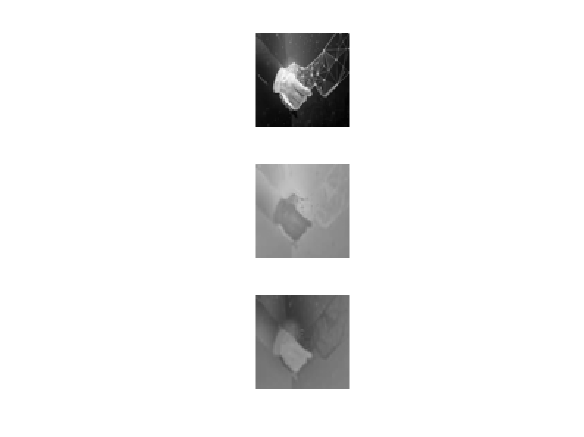


hand64_YCC = RGB2YCbCr_img(hand64);
figure
subplot(3, 1, 1)
imshow(hand64_YCC(:, :, 1), 'InitialMagnification', 400)
subplot(3, 1, 2)
imshow(hand64_YCC(:, :, 2), 'InitialMagnification', 400)
subplot(3, 1, 3)
imshow(hand64_YCC(:, :, 3), 'InitialMagnification', 400)

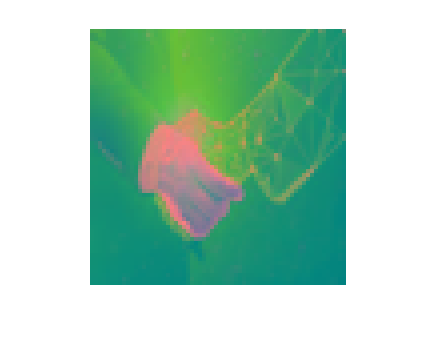

figure
imshow(hand64_YCC, 'InitialMagnification', 400)

%colorThresholder(hand64_YCC);
%imwrite(BW,"hand64_BM.png")

hand_BW = imread("hand64_BM.png")

hand_BW = 64×64 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

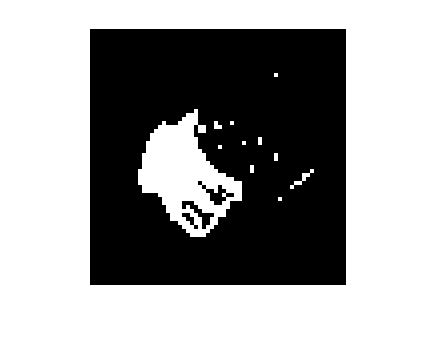

figure
imshow(hand_BW, 'InitialMagnification', 400)

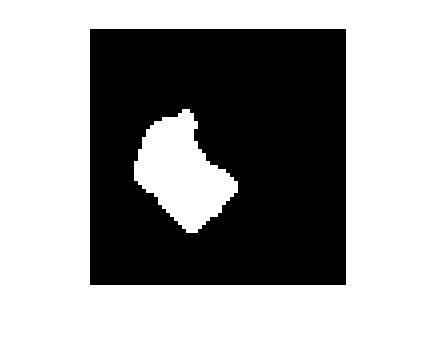

hand64_mask_filt = medfilt2(hand_BW,[4 4]);
hand64_mask_filt = medfilt2(hand64_mask_filt,[4 4]);
figure
imshow(hand64_mask_filt, 'InitialMagnification', 400)

props = regionprops(hand64_mask_filt);
xCOM = props.Centroid(1)

xCOM = 23.5439

yCOM = props.Centroid(2)

yCOM = 36.5197

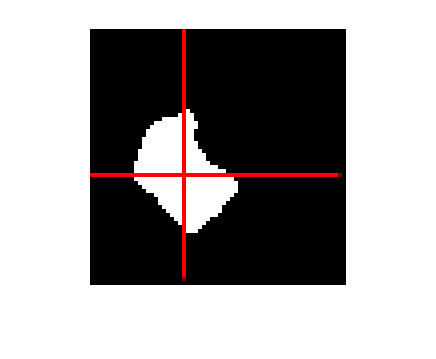


hand64_out = 255 * repmat(uint8(hand64_mask_filt), 1, 1, 3);
hand64_out = insertShape(hand64_out, 'line', [xCOM 0 xCOM 63], 'Color','red');
hand64_out = insertShape(hand64_out, 'line', [0 yCOM 63 yCOM], 'Color','red');

figure, imshow(hand64_out, 'InitialMagnification', 400);

%hold on;
%rectangle('Position', props.BoundingBox, 'EdgeColor', 'g')

imwrite(hand64_out,"hand64_out.ppm")

function [output] = RGB2YCbCr(input)
    A = [[0.299 0.587 0.114];
         [-0.168736 -0.331264 0.5];
         [0.5 -0.418688 -0.081312]];
    B = [0; 128; 128];
    x = double(input(:,:)');
    output = A*x + B;
end %RGB2YCbCr


function [out_img] = RGB2YCbCr_img(in_img)
out_img = zeros(size(in_img));
for i = 1:64
    for j = 1:64
        out_img(i, j, :) = RGB2YCbCr(in_img(i, j, :));
    end %for
end %for
out_img = cast(out_img, 'uint8');
end